Rectangular function with respect to M=10


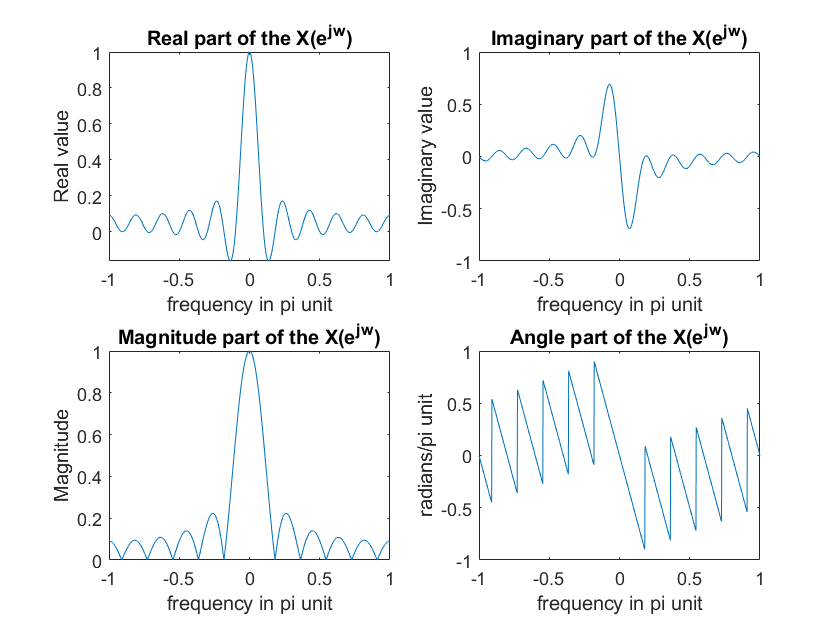

Rectangular function with respect to M=25


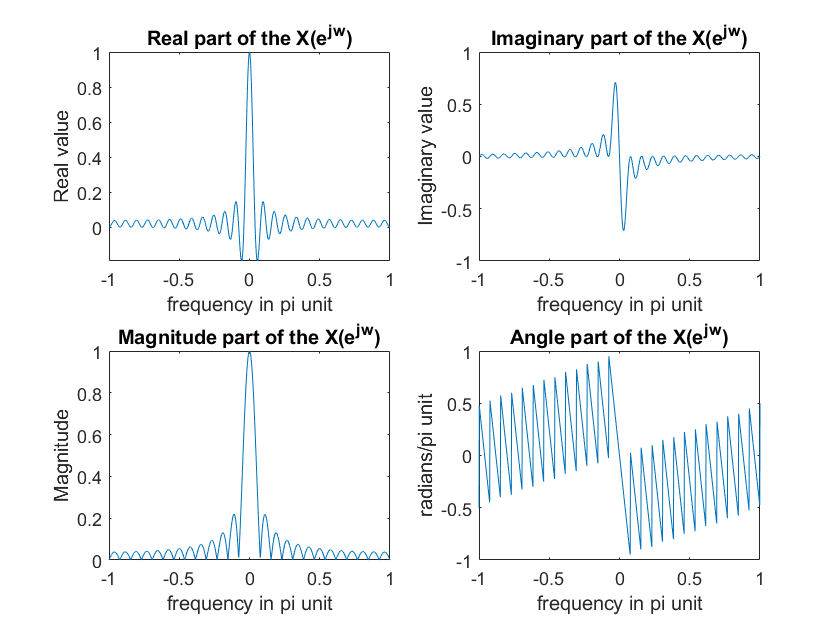

Rectangular function with respect to M=50


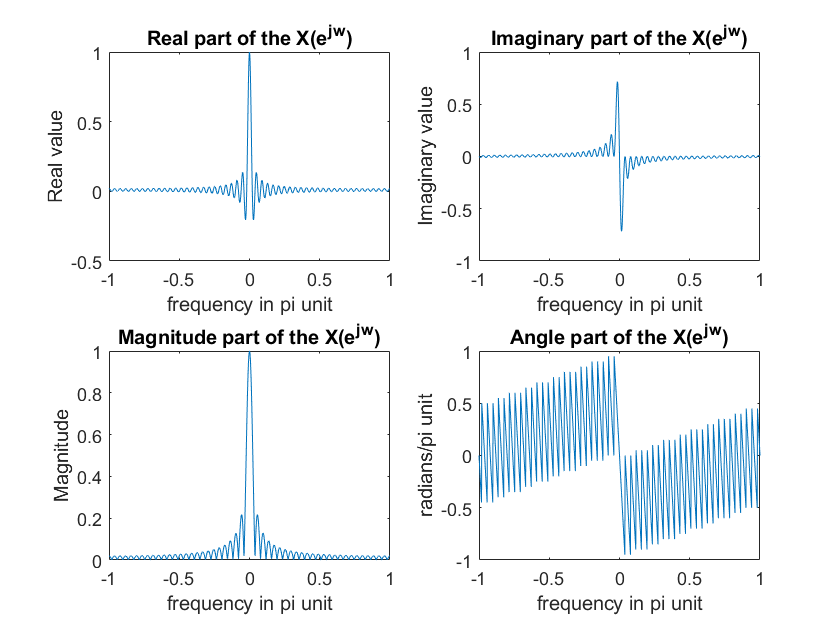

Rectangular function with respect to M=101


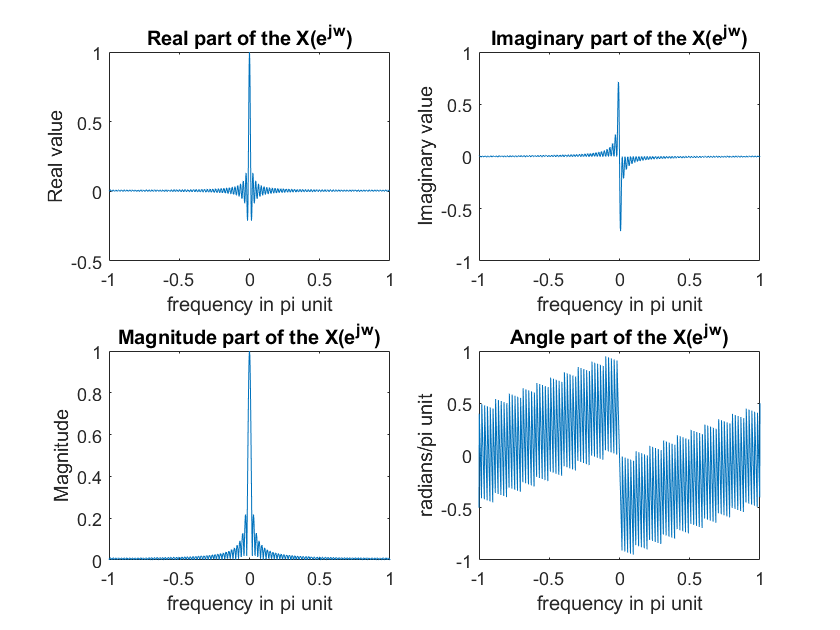

% Rectangular window
K=500;
k=-K:K;
w=(pi*k)/K;

M=[10 25 50 101];
for i=1:length(M)
    figure('Name',strcat('M= ',num2str(M(i))))
    n=-50:M(i);
    rect=unitseq(min(n),M(i),0); %rectangular window function
    X=dtft(rect,n,w);
    disp(strcat('Rectangular window function with respect to M=',num2str(M(i))))
    dfp4(X/max(X),w)
end